Funcao

funct_ex5(20,6,10000)

ans = 0.0376

funct_ex5(40,6,10000)

ans = 0

funct_ex5(100,6,10000)

ans = 0

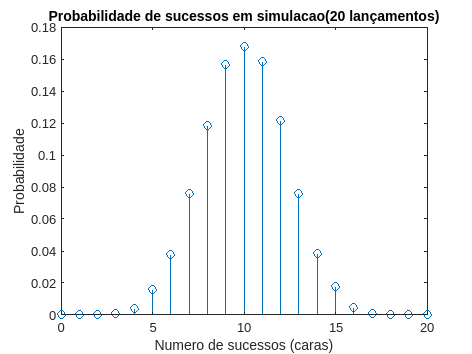

% Definir range
caras_range = 0:20;

% Definir parametros
nlancamentos = 20; % Number of tosses
nexperiencias = 10000; % Number of simulations

% Array
probabilities = zeros(1, numel(caras_range));

% Calcular probabilidade de cada numero de sucessos
for i = 1:numel(caras_range)
    probabilities(i) = funct_ex5(nlancamentos, caras_range(i), nexperiencias);
end

stem(caras_range, probabilities)
xlabel('Numero de sucessos (caras)')
ylabel('Probabilidade')
title('Probabilidade de sucessos em simulacao(20 lançamentos)')

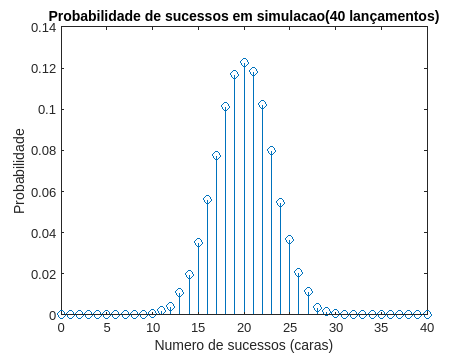

caras_range = 0:40;

nlancamentos = 40; % Number of tosses
nexperiencias = 10000; % Number of simulations

probabilities = zeros(1, numel(caras_range));

for i = 1:numel(caras_range)
    probabilities(i) = funct_ex5(nlancamentos, caras_range(i), nexperiencias);
end

stem(caras_range, probabilities)
xlabel('Numero de sucessos (caras)')
ylabel('Probabilidade')
title('Probabilidade de sucessos em simulacao(40 lançamentos)')

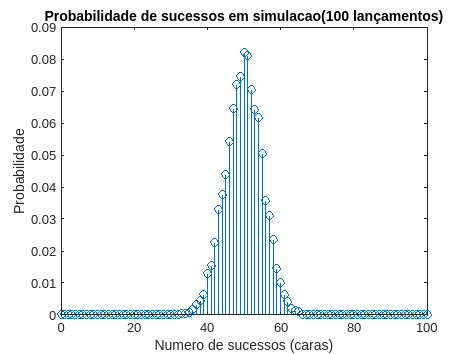

% Definir range
caras_range = 0:100;

% Definir parametros
nlancamentos = 100; % Number of tosses
nexperiencias = 10000; % Number of simulations

% Array
probabilities = zeros(1, numel(caras_range));

% Calculate probabilities for different numbers of successes
for i = 1:numel(caras_range)
    probabilities(i) = funct_ex5(nlancamentos, caras_range(i), nexperiencias);
end

stem(caras_range, probabilities)
xlabel('Numero de sucessos (caras)')
ylabel('Probabilidade')
title('Probabilidade de sucessos em simulacao(100 lançamentos)')

function [probSimulacao] = funct_ex5(nlancamentos,caras,nexperiencias)
%EX5 Summary of this function goes here
%   Detailed explanation goes here

lancamentos=rand(nlancamentos,nexperiencias);
totalcaras=lancamentos>0.5;
sucessos=sum(totalcaras)==caras;
probSimulacao= sum(sucessos)/nexperiencias;
end